clear all
load("acetate_maint0.txt")
%h=figure('Units','inches','Position',[0 0 1.25 0.9])
acetate(1:1000)=0.0;
for t=1:length(acetate_maint0)
    acetate(t)=acetate_maint0(t,3);
end
ac0=acetate;

figure
%colororder(["#FF00FF","#0000FF","#00FF00","#FF0000"])
plot(0.05*5*[1:100]/24,ac0(1:100),'LineWidth',2,'Color','magenta')
%xlim([0,0.6])
%xlabel('Time [days]','FontSize',15)
%ylabel('Glucose [mmol/cm^2]','FontSize',15)
%ylim([0 3.5e-3])
%xticklabels(gcf,'FontSize',10)
ax=gca;
ax.FontSize=18

ax =   Axes with properties:

             XLim: [0 1.0417]
             YLim: [0 0.0400]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


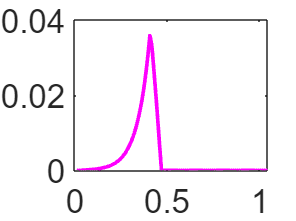

hold on

load("acetate_maint4.txt")
%h=figure('Units','inches','Position',[0 0 1.25 0.9])
acetate(1:1000)=0.0;
for t=1:length(acetate_maint4)
    acetate(t)=acetate_maint4(t,3);
end
ac4=acetate;

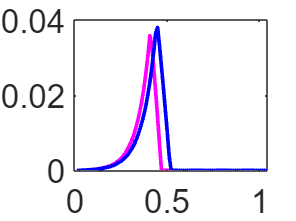


plot(0.05*5*[1:100]/24,ac4(1:100),'LineWidth',2,'Color','blue')
hold on

load("acetate_maint8.txt")
%h=figure('Units','inches','Position',[0 0 1.25 0.9])
acetate(1:1000)=0.0;
for t=1:length(acetate_maint8)
    acetate(t)=acetate_maint8(t,3);
end
ac8=acetate;

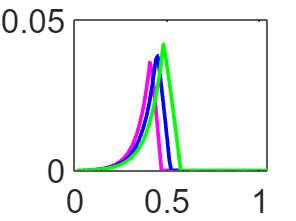


plot(0.05*5*[1:100]/24,ac8(1:100),'LineWidth',2,'Color','green')
hold on

load("acetate_maint16.txt")
%h=figure('Units','inches','Position',[0 0 1.25 0.9])
acetate(1:1000)=0.0;
for t=1:length(acetate_maint16)
    acetate(t)=acetate_maint16(t,3);
end
ac16=acetate;

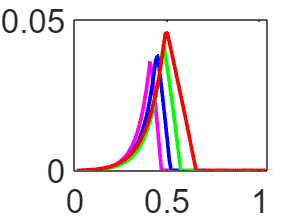

plot(0.05*5*[1:100]/24,ac16(1:100),'LineWidth',2,'Color','red')
hold on

colororder(["#FF00FF","#0000FF","#00FF00","#FF0000"])

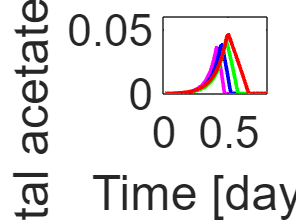

ax =   Axes with properties:

             XLim: [0 0.8000]
             YLim: [0 0.0600]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2048 0.2071 0.7002 0.7179]
            Units: 'normalized'

  Show all properties


xlim([0,0.8])
ylim([0,0.6e-1])
xlabel('Time [days]','FontSize',15)
ylabel('Total acetate [mmol]','FontSize',15)
%ylim([0 3.5e-3])
%xticklabels(gcf,'FontSize',10)
ax=gca;
ax.FontSize=24

%colororder(["#FF00FF","#0000FF","#00FF00","#FF0000"])

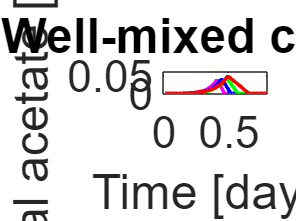

title('Well-mixed culture')
%legend('ATP Maintenance Req. = 0 [mmol/g h]','ATP Maintenance Req. = 4 [mmol/g h]','ATP Maintenance Req. = 8 [mmol/g h]','ATP Maintenance Req. = 16 [mmol/g h]','FontSize',10)
saveas(gcf,'acetate.png')